Exercise 2 (c) - 1

[imp, impn] = impseq(0, -5, 5)

imp = 1×11 logical 배열
   0   0   0   0   0   1   0   0   0   0   0


impn =     -5    -4    -3    -2    -1     0     1     2     3     4     5


h_1 = [5 2 3 -5 1 11]

h_1 =      5     2     3    -5     1    11


h_1_n = -1:4

h_1_n =     -1     0     1     2     3     4



[y, ny] = conv_m(h_1, h_1_n, imp, impn)

y =      0     0     0     0     0     5     2     3    -5     1    11     0     0     0     0     0


ny =     -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9


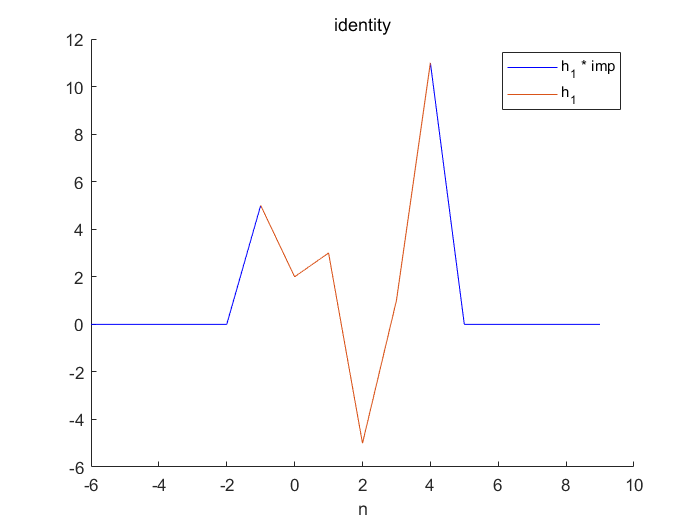


hold on
plot(ny, y, 'b')
plot(h_1_n, h_1)
title('identity');
xlabel('n');
legend('h_1 * imp', 'h_1')
hold off

Exercise 2 (c) - 2

x_n = -5:5

x_n =     -5    -4    -3    -2    -1     0     1     2     3     4     5


x = [0 0 4 13 6 -3 -1 2 4 0 0]

x =      0     0     4    13     6    -3    -1     2     4     0     0


h_2_n = -1:4

h_2_n =     -1     0     1     2     3     4


h_2 = [-4 2 0 6 3 1]

h_2 =     -4     2     0     6     3     1


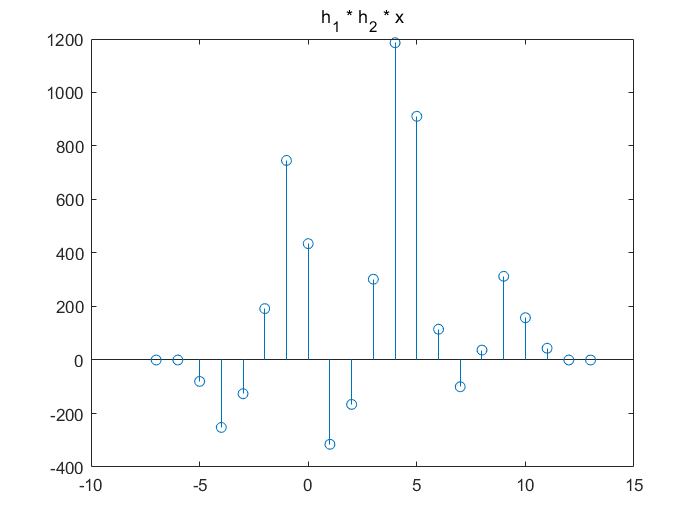

[tmp, tmpn] = conv_m(h_1, h_1_n, h_2, h_2_n);
[y1, ny] = conv_m(tmp, tmpn, x, x_n);
stem(ny, y1)
title('h_1 * h_2 * x');


[tmp, tmpn] = conv_m(h_2, h_2_n, h_1, h_1_n);
[y2, ny] = conv_m(tmp, tmpn, x, x_n)

y2 =            0           0         -80        -252        -126         192         746         435        -315        -166         302        1186         911         115        -100          37         313         158          44           0           0


ny =     -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13


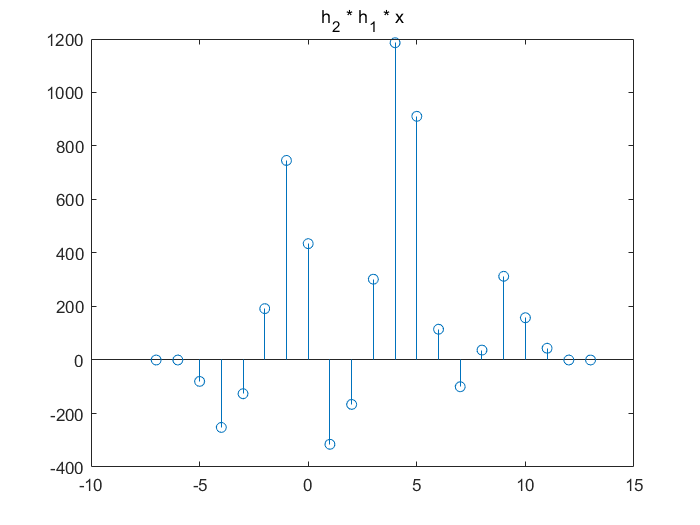

stem(ny, y2)
title('h_2 * h_1 * x');

error = y1 - y2

error =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


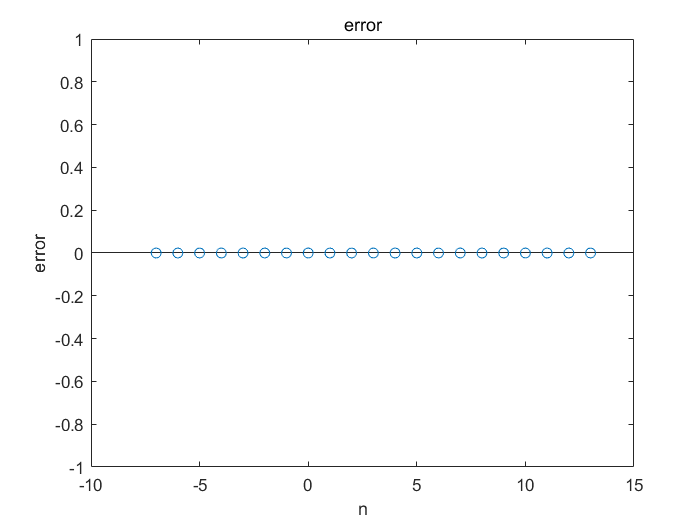

stem(ny, error)
title('error');
xlabel('n');
ylabel('error');